Initial value problem of three coupled first order ODE

% initial values
t_span = [0 5];
y_init = [1 2 3];


[t,y] = ode45(@diff_eqs, t_span, y_init)

t =          0
    0.0066
    0.0132
    0.0199
    0.0265
    0.0596
    0.0927
    0.1259
    0.1590
    0.2176


y =     1.0000    2.0000    3.0000
    1.0498    1.9809    2.9825
    1.0987    1.9623    2.9649
    1.1467    1.9443    2.9472
    1.1938    1.9268    2.9294
    1.4163    1.8496    2.8399
    1.6173    1.7906    2.7507
    1.7975    1.7484    2.6628
    1.9580    1.7186    2.5770
    2.1973    1.6763    2.4310


y(end,:)

ans =     0.2378    0.9722   -0.2608


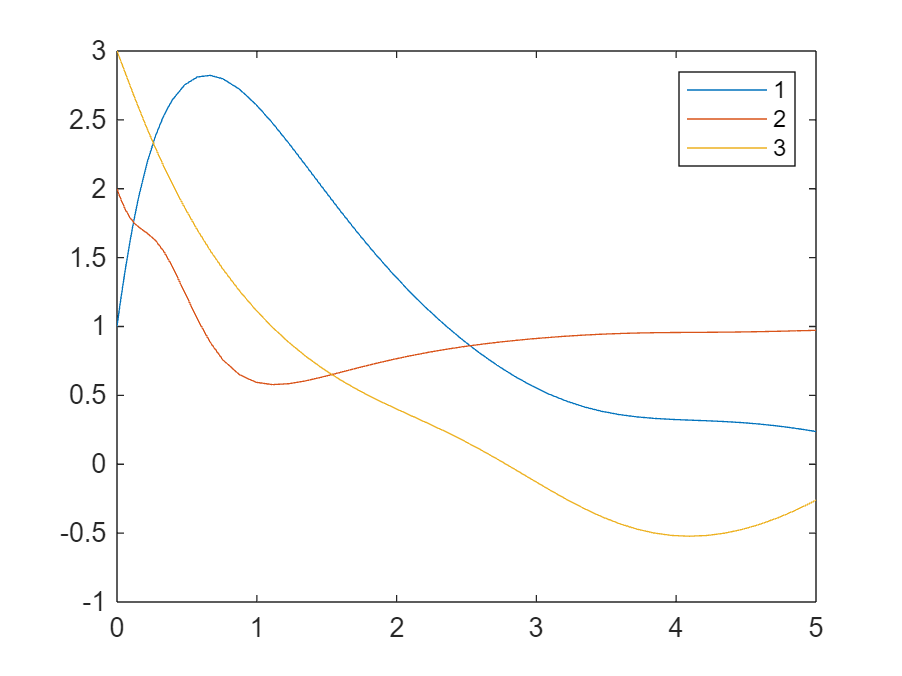

legend("1", "2", "3")

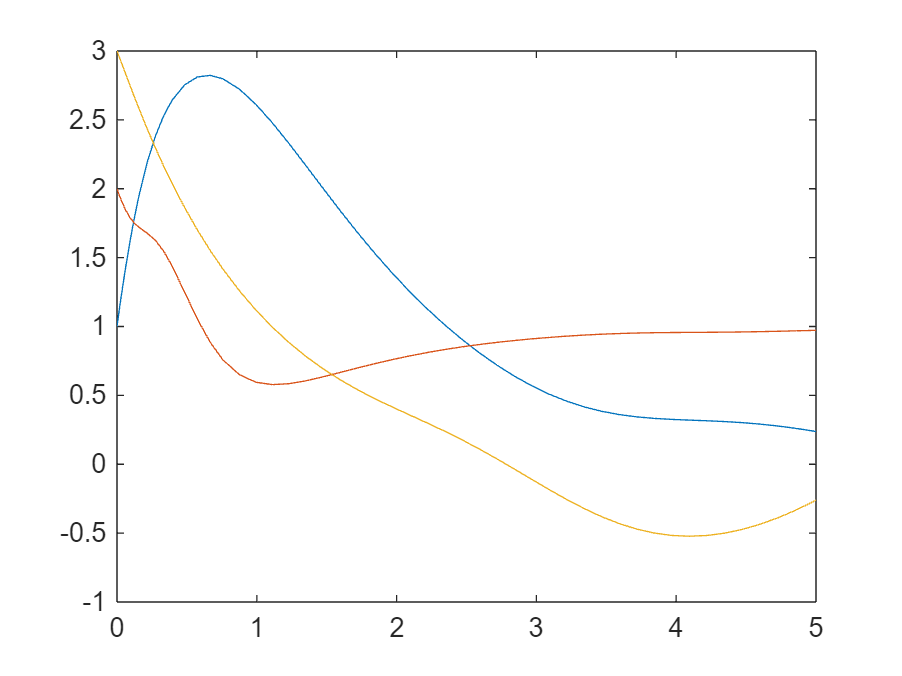

plot(t,y)

Brief summary of this function.

Detailed explanation of this function.

function dydt = diff_eqs(t, y)
dydt = [exp(-t)*cos(y(2))+y(3)^2-y(1);
cos(y(3)^2)-y(2);
cos(t)*exp(-y(1)^2)-y(3)];
end